## `Preprocessing Satellite and UAV Image`

% rotate sat image
I = imread("data_set/satellite_image.png");
J = imrotate(I,90);
imwrite(J, 'rot_90_satellite_image.png');

% crop sat image
I = imread("data_set/rot_90_satellite_image.png");
Icropped = imcrop(I);
imwrite(Icropped, '2020-11-24_071716_85_001460_sat.png')

% rescale the sat and uav image
read_path = './Akagi_DataSet/2020-11-24_071716/raw_undistorted/';
fixed = imread(append(read_path,'2020-11-24_071716_85_001500_sat.png'));
moving = imread(append(read_path,'2020-11-24_071716_85_001500_uav.png'));
moving = imresize(moving,0.35);
imshowpair(fixed, moving, "montage");

out_shape = [192, 192];
o_fixed = imresize(fixed,out_shape);
o_moving = imresize(moving,out_shape);
imshowpair(o_fixed, o_moving, "montage");

save_path = './Akagi_DataSet/2020-11-24_071716/dlk_data/';
imwrite(o_fixed, append(save_path,'58_sat.jpg'));
imwrite(o_moving, append(save_path,'58_uav.jpg'));

## `Satellite and UAV Image Registration`

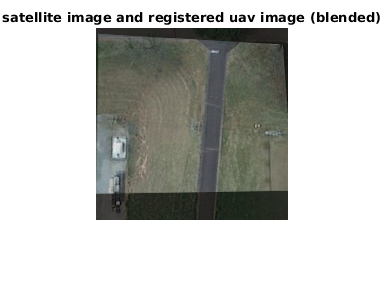

% use the tool to find homography between raw satellite and uav image
read_path = './Akagi_DataSet/2020-11-24_071716/dlk_data/';
fixed_sat_img = imread(append(read_path,'2_sat.jpg'));
moving_uav_img = imread(append(read_path,'2_uav.jpg'));

if exist('mp','var') == 0
    % open cpselect tool if mp and corresponding fp not exists
    [mp,fp] = cpselect(moving,fixed_sat_img,'Wait',true);
end

%% compute homography from fp and mp %%
t = fitgeotrans(mp,fp,'projective');
gt_H = transpose(t.T);    %% gt homography matrix %%
Rfixed = imref2d(size(fixed_sat_img));
registered_uav_img = imwarp(moving_uav_img,t,'OutputView',Rfixed);
imshowpair(fixed_sat_img,registered_uav_img,'blend');
title('satellite image and registered uav image (blended)')

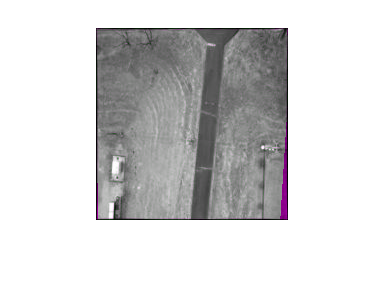


%% find transformation of tgt_points of uav_img in sat_img %%
tgt_points = [[32 32];[159 32];[32 159]; [159 159]]; % these corner points are fixed as in DLK paper
src_points = transformPointsForward(t,tgt_points);   %% gt corner points for DLK method %%

%% verification of homography i.e. simulated_drone_img == raw uav image %%
tInv = invert(t);
simulated_drone_img = imwarp(registered_uav_img,tInv,'OutputView',Rfixed);
imshowpair(simulated_drone_img, moving_uav_img, "falsecolor");

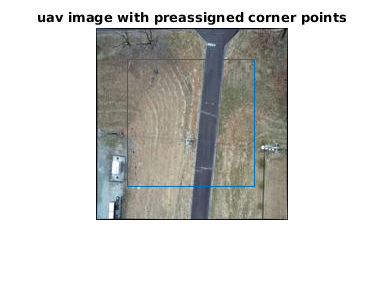


%% tgt_points w.r.t. uav image %%
imshow(moving_uav_img);
title('uav image with preassigned corner points')
line([tgt_points(1, 1),tgt_points(2, 1)], [tgt_points(1, 2),tgt_points(2, 2)]);
line([tgt_points(2, 1),tgt_points(4, 1)], [tgt_points(2, 2),tgt_points(4, 2)]);
line([tgt_points(1, 1),tgt_points(3, 1)], [tgt_points(1, 2),tgt_points(3, 2)]);
line([tgt_points(3, 1),tgt_points(4, 1)], [tgt_points(3, 2),tgt_points(4, 2)]);

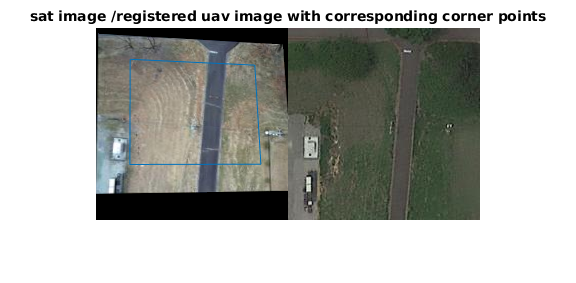


%% src_points w.r.t. satellite image / registered uav image %%
imshowpair(registered_uav_img, fixed_sat_img, "montage");
title('sat image /registered uav image with corresponding corner points')
line([src_points(1, 1),src_points(2, 1)], [src_points(1, 2),src_points(2, 2)]);
line([src_points(2, 1),src_points(4, 1)], [src_points(2, 2),src_points(4, 2)]);
line([src_points(1, 1),src_points(3, 1)], [src_points(1, 2),src_points(3, 2)]);
line([src_points(3, 1),src_points(4, 1)], [src_points(3, 2),src_points(4, 2)]);

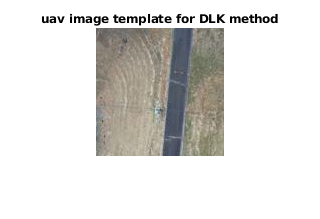


%% save src_points as gt and [128, 128] template uav image %%
template = moving_uav_img(32:159,32:159,:);
assert(all(size(template) == [128, 128, 3]))
imshow(template);
title('uav image template for DLK method')

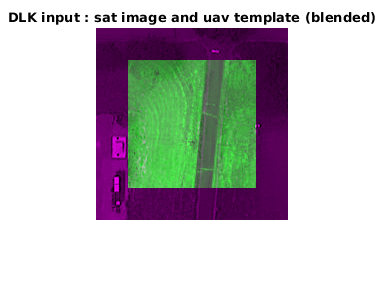

imwrite(template, '58_uav_template.jpg');

% ----------------------------------

%% DLK input: before transformation %%
dlk_template = padarray(template,[32 32],0,'both'); % [128, 128] template img in DLK method that need to be transformed
dlk_input = fixed_sat_img;   % [192, 192] input img in DLK method
gt_output = registered_uav_img;   % [192, 192] gt transformed img
imshowpair(dlk_template, dlk_input, "falsecolor");
title('DLK input : sat image and uav template (blended)')

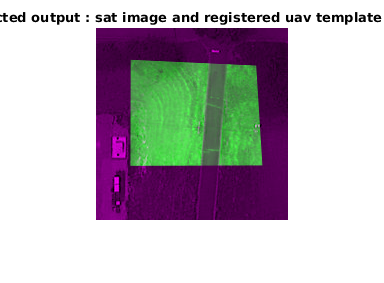

%% DLK expected output: after transformation %%
registered_dlk_template = imwarp(dlk_template,t,'OutputView',Rfixed);
% imshowpair(registered_dlk_template, gt_output, "falsecolor");
imshowpair(registered_dlk_template, dlk_input, "falsecolor");
title('DLK expected output : sat image and registered uav template (blended)')